%addpath 'iwave\development\matlab'

load_parameters

t_end = 0.01; % secs
t = 0 : t_step : t_end;

%% generate signal and noise
f_axion = generate_axion_frequency_maxwellian(t, f_sampling, t_coherence, f_a, axion_linewidth);
noise_power = calculate_noise_power(f_sampling, 10e-3);
noise = generate_thermal_noise(t, noise_power);

f_0 = f_a;
f_0_original = f_a_original;
Q_resonator_original = 1e6;
Q_resonator = Q_resonator_original / heterodyning_ratio;
band_width = f_0 / Q_resonator

band_width = 483.5590

band = [f_0-band_width/2, f_0+band_width/2];
limiting_band = [f_0-2*band_width, f_0+2*band_width];

%% finish generation
signal = generate_axion_signal(t, f_sampling, f_axion, axion_power_over_Q * Q_resonator_original);

tau_iwave = 8e-5;
f_guess = f_0;

%R = @(Q, df, f_res_o) 1 ./ (1 + 4*Q^2 * df.^2 ./ f_res_o.^2 );

STATE_PS = iwave_setup(f_sampling, tau_iwave, f_guess, 0);
state_res = resonator_setup();
f_iwave = zeros(size(t));
f_0_current = f_0
for i = 1 : length(t)
    resonator_input = noise(i) + signal(i);

f_0_current = 2.4178e+07

    [state_res, resonator_output] = resonator_step2(state_res, resonator_input, f_0_current, band_width, f_sampling);
    iwave_input = resonator_output;
    [STATE_PS, pdout, pqout, paout, peout, pfout, pfstateout] = iwave_step(STATE_PS, iwave_input);
    f_0_current = pfout;
    if f_0_current > limiting_band(2)
        f_0_current = limiting_band(2);
    elseif f_0_current < limiting_band(1)
        f_0_current = limiting_band(1);
    end
    f_iwave(i) = f_0_current;
end

% front to chop off
start_secs = 0.001;
assert(start_secs < t(end)/3);
start = round(start_secs * f_sampling);

% don't need to plot every single point
div = 1000;

slice = (1:div:length(t));
t_small       = t(slice);
f_axion_small = f_axion(slice);
f_iwave_small = f_iwave(slice);

start_small = round(start / div)

start_small = 250

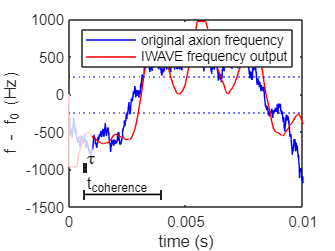

figure
%adstyle(8, 8);

plot(t_small(start_small:end), f_axion_small(start_small:end)-f_0, 'Color', [0,0,1], 'DisplayName','original axion frequency')
y_lim = ylim();
hold on
plot(t_small(1:start_small),   f_axion_small(1:start_small)  -f_0, 'Color', [0.8,0.8,1], 'HandleVisibility','off')
plot(t_small(start_small:end), f_iwave_small(start_small:end)-f_0, 'Color', [1,0,0], 'DisplayName','IWAVE frequency output')
plot(t_small(1:start_small),   f_iwave_small(1:start_small)  -f_0, 'Color', [1,0.8,0.8], 'HandleVisibility','off')
%ylim(y_lim)
legend()
xlabel('time (s)')
ylabel('f - f_0 (Hz)')

y_lim = ylim();
x_lim = xlim();
y_width = y_lim(2) - y_lim(1);
x_width = x_lim(2) - x_lim(1);
x_start = x_lim(1) + x_width/15;
y_1 = y_lim(1) + y_width/15;
y_2 = y_1 + y_width/7;
plot([x_start, x_start + t_coherence], [y_1, y_1], '-|', 'Color','black', 'LineWidth',1, 'HandleVisibility','off')
plot([x_start, x_start + tau_iwave], [y_2, y_2], '-|', 'Color','black', 'LineWidth',1, 'HandleVisibility','off')
text(x_start, y_1 + y_width/20, 't_{coherence}')
text(x_start, y_2 + y_width/20, '\tau')

%plot(t_small, f_iwave_small - band_width/2 -f_0, ':r', 'HandleVisibility','off')
%plot(t_small, f_iwave_small + band_width/2 -f_0, ':r', 'HandleVisibility','off')
yline([f_a-axion_linewidth/2 - f_0, f_a + axion_linewidth/2 - f_0], ':b', 'HandleVisibility','off')

% figure
% R_ = R(f_axion, f_iwave);
% %R_small = R_(slice);
% plot(t, R_);
% set(gca, 'yscale', 'log')

% powers = zeros(1, floor(length(INPUT_DATA)/1000));
% j = 0;
% for i = 1 : 1000 : length(INPUT_DATA) - 1000
%     j = j+1;
%     powers(j) = bandpower(xs(i:i+1000));
% end
% 
% figure
% plot(t_small(1:end-1), powers)
% set(gca, 'yscale','log')

rms(f_axion(start:end) - f_iwave(start:end))

ans = 308.1425

rms(f_axion(start:end) - f_0)

ans = 468.3592

%rms(f_axion(start:(end+1)/2) - f_iwave(start:(end+1)/2))
%rms(f_axion(start:(end+1)/2) - f_0)